# Gaussian Mean Time Series Filter

- y(t) = sum(x(i)*g(i)) i=t-k to t+k

- g(i) normalizes y(i)

- g = e^((-4ln(2)*t^2)/w^2) *different formulation! allows for full width at half maximum to be specified.

- smoother filter than running mean filter

### create signal

freq = 1000; %hz
t    = 0:(1/freq):10; %10 second sample
n    = length(t);
p    = 12; %for interpolation

noise = 4;
sigc  = interp1(rand(p,1)*24, linspace(1,p,n));
noise = noise * randn(size(t));
sign  = sigc + noise; %noisy signal

### plot the signals

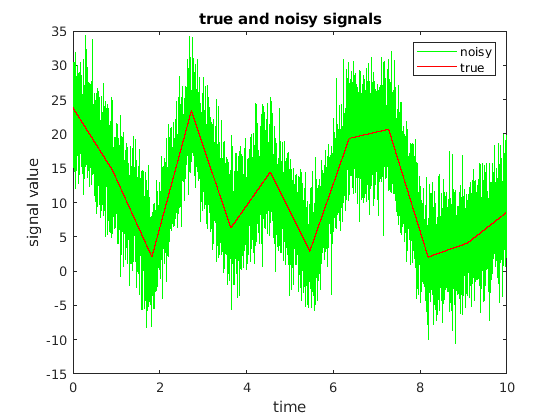

noisy = plot(t, sign, 'g');
hold on;
true = plot(t, sigc, 'r-');
hold off;
title("true and noisy signals");
xlabel("time");
ylabel("signal value");
legend([noisy,true], ["noisy", "true"]);

### create the gaussian filter

- lower bound for k ensures gaussian approaches 0, upper bound prevents edge effects

- try different values to find a suitable number

- w determines the filter size (higher w, more smoothing)

w = 50.49602; %window size in ms
k = 70; %ms, 1/2 range for gaussian to approach 0 (try values between 10 and 100 to see)
gt = 1000*(-k:k)/freq; %time vector in ms

gw = exp(-(4*log(2)*gt.^2)/w^2); %gaussian window

p0 = k+dsearchn(gw(k+1:end)',.5); %find the w line
p1 = dsearchn(gw(1:k)', .5);

w_emp = gt(p0) - gt(p1); %actual w based on sampling

### Display the gaussian filter

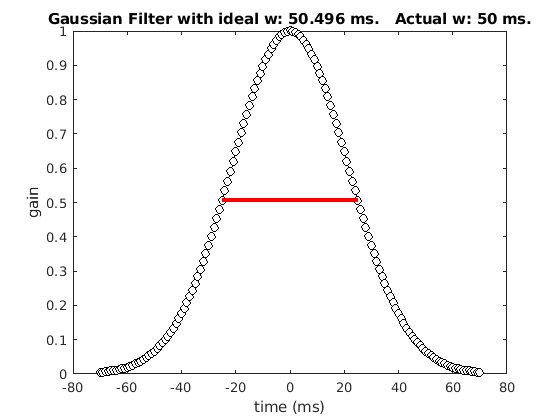

figure(1);
plot(gt, gw, 'ko-', 'markerfacecolor', 'w', 'linew',1);
hold on;
plot(gt([p0 p1]), gw([p0 p1]), 'r', 'linew', 3);
hold off;
gw = gw/sum(gw); %normalize to sample size
title(['Gaussian Filter with ideal w: ' num2str(w) ' ms.   Actual w: ' num2str(w_emp) ' ms.']);
xlabel("time (ms)");
ylabel("gain");

### Implement the gaussian filter

filtered = sign;

for i = k+1:n-k-1
    filtered(i) = sum(sign(i-k:i+k).*gw);
end

### Plot the filtered signal

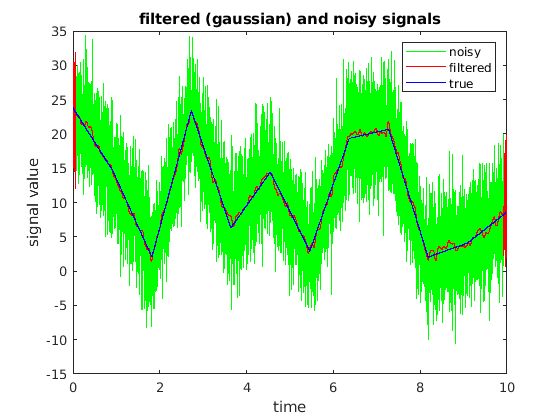

figure(2);
noisy = plot(t, sign, 'g');
hold on;
filtered = plot(t, filtered, 'r-');
true = plot(t, sigc, 'b-');
hold off;
title("filtered (gaussian) and noisy signals");
xlabel("time");
ylabel("signal value");
legend([noisy,filtered,true], ["noisy", "filtered", "true"]);